# Homework 5

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1. 

### Part a.)

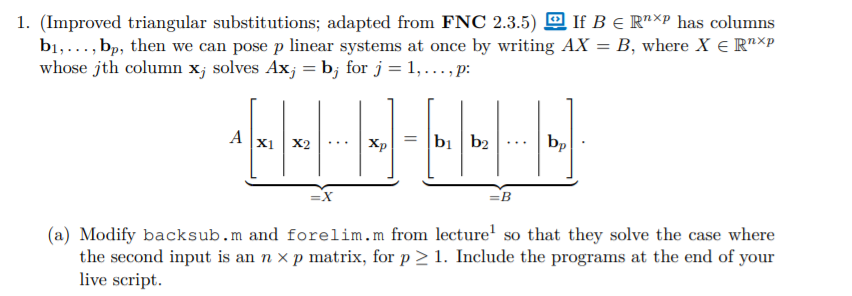

%Programs included at end of livescript

### Part b.)

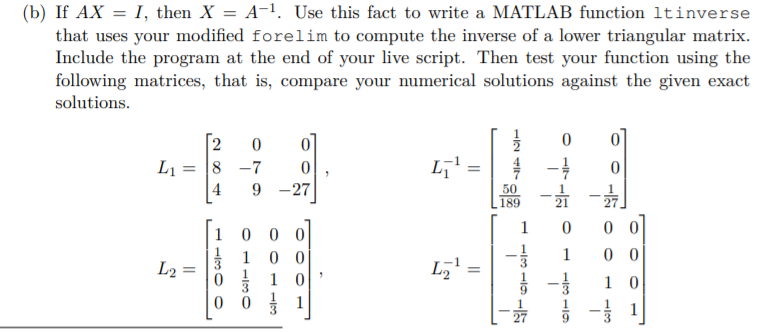

format rat
L1 = [2 0 0; 8 -7 0; 4 9 -27]

L1 =        2              0              0       
       8             -7              0       
       4              9            -27       


X = ltInverse(L1)

X =        1/2            0              0       
       4/7           -1/7            0       
      50/189         -1/21          -1/27    


L2 = [1 0 0 0; (1/3) 1 0 0; 0 (1/3) 1 0; 0 0 (1/3) 1]

L2 =        1              0              0              0       
       1/3            1              0              0       
       0              1/3            1              0       
       0              0              1/3            1       


X = ltInverse(L2)

X =        1              0              0              0       
      -1/3            1              0              0       
       1/9           -1/3            1              0       
      -1/27           1/9           -1/3            1       


## Problem 2. 

### Part a.)

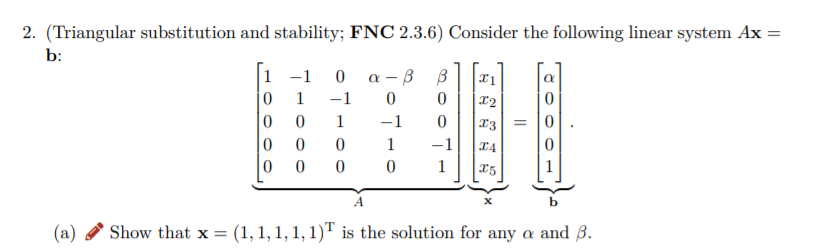

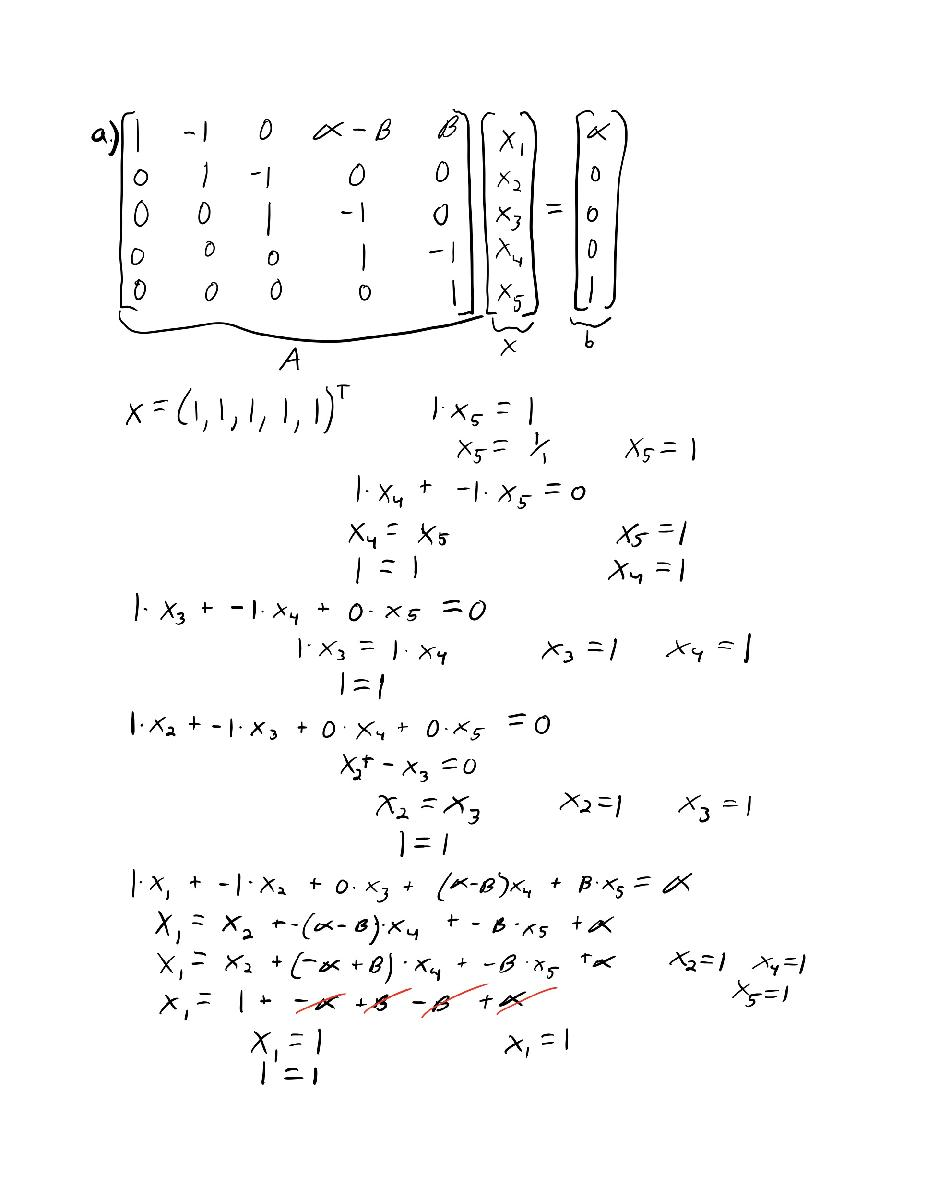

### Part b.)

format long g
alpha = 0.1;
beta = 10 .^ [1:12];
b = [alpha 0 0 0 1]';
fprintf('Beta                  |x1 - 1|')

Beta                  |x1 - 1|

fprintf('-------------------------------')

-------------------------------

for i = 1:12
    A = [1 -1 0 alpha-beta(:,i) beta(:,i); 
         0 1 -1 0 0; 0 0 1 -1 0; 
         0 0 0 1 -1; 
         0 0 0 0 1];
    x = A \ b;
    fprintf('%13d   %12d\n',B(:,i), abs(x(1)-1))
end

           10              0
          100              0
         1000              0
        10000              0
       100000              0
      1000000              0
     10000000              0
    100000000              0
   1000000000              0
  10000000000              0
 100000000000              0
1000000000000              0



for i = 1:12
    A = [1 -1 0 alpha-beta(:,i) beta(:,i); 
         0 1 -1 0 0; 0 0 1 -1 0; 
         0 0 0 1 -1; 
         0 0 0 0 1];
    x = backsub(A, b);
    fprintf('%13d   %12.12f\n',B(:,i), abs(x(1)-1))
end

           10   0.000000000000
          100   0.000000000000
         1000   0.000000000000
        10000   0.000000000000
       100000   0.000000000006
      1000000   0.000000000023
     10000000   0.000000000373
    100000000   0.000000005960
   1000000000   0.000000023842
  10000000000   0.000000381470
 100000000000   0.000006103516
1000000000000   0.000024414063


As we see here in the two loops the basic \ loop gives us zeroes back while the second does not, this is because catastrophic cancellation is occurring in the first loop which leads to some of the values after the decimal  being lost and it just gives us zero back versus the second using backsub which gives us more decimal values back

## Problem 3. 

### Part a.)

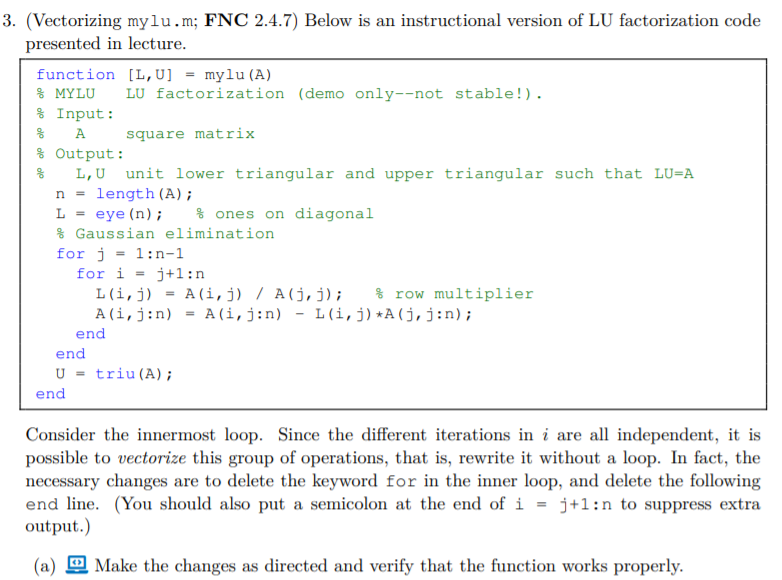

A = [2 2 1; -4 6 1; 5 -5 3];
%Check to make sure function works properly
[L, U] = mylu(A)

L =                          1                         0                         0
                        -2                         1                         0
                       2.5                        -1                         1


U =                          2                         2                         1
                         0                        10                         3
                         0                         0                       3.5


[L, U] = myluMod(A)

L =                          1                         0                         0
                        -2                         1                         0
                       2.5                        -1                         1


U =                          2                         2                         1
                         0                        10                         3
                         0                         0                       3.5


%Functions found at end of livescript

### Part b.)

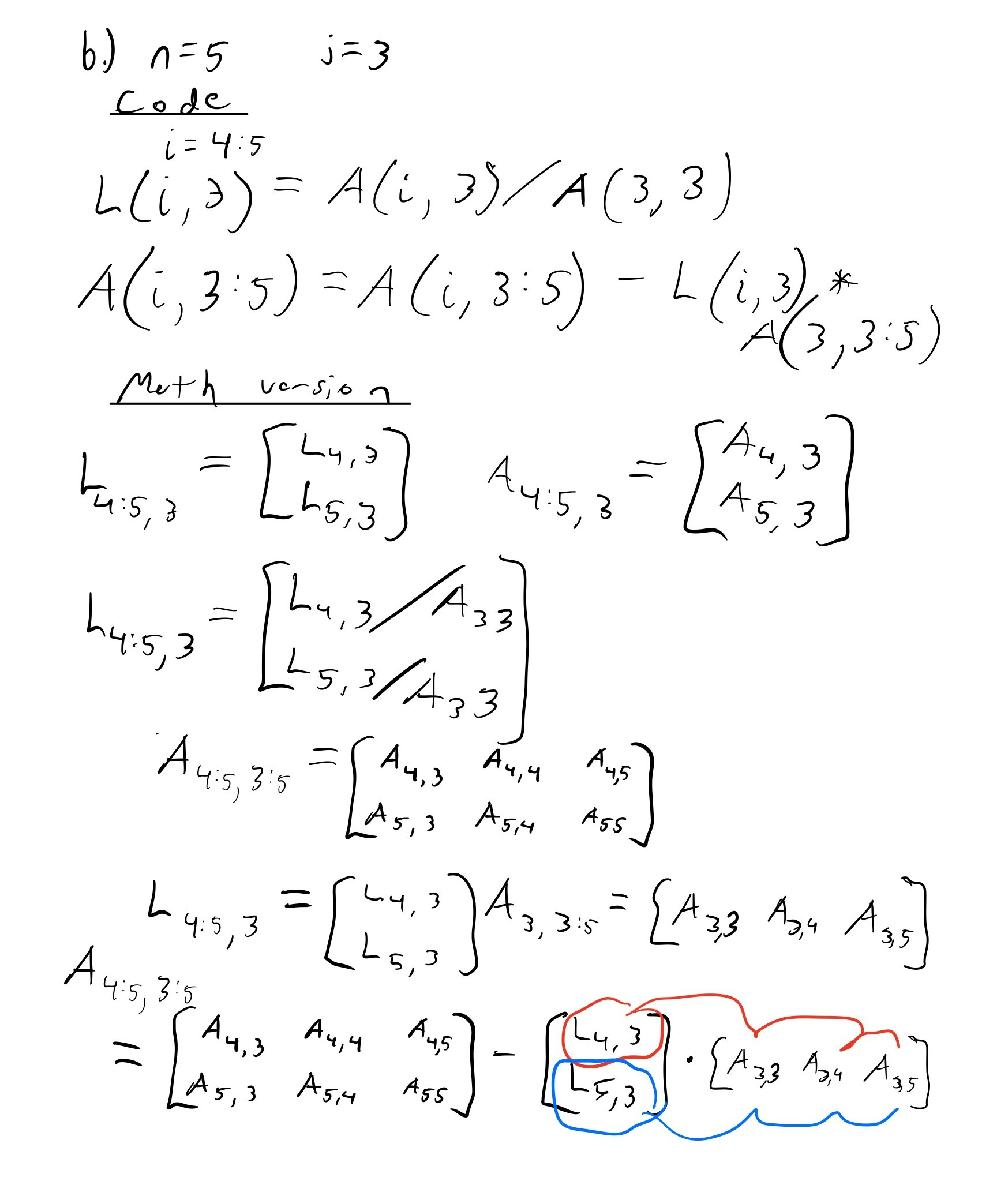

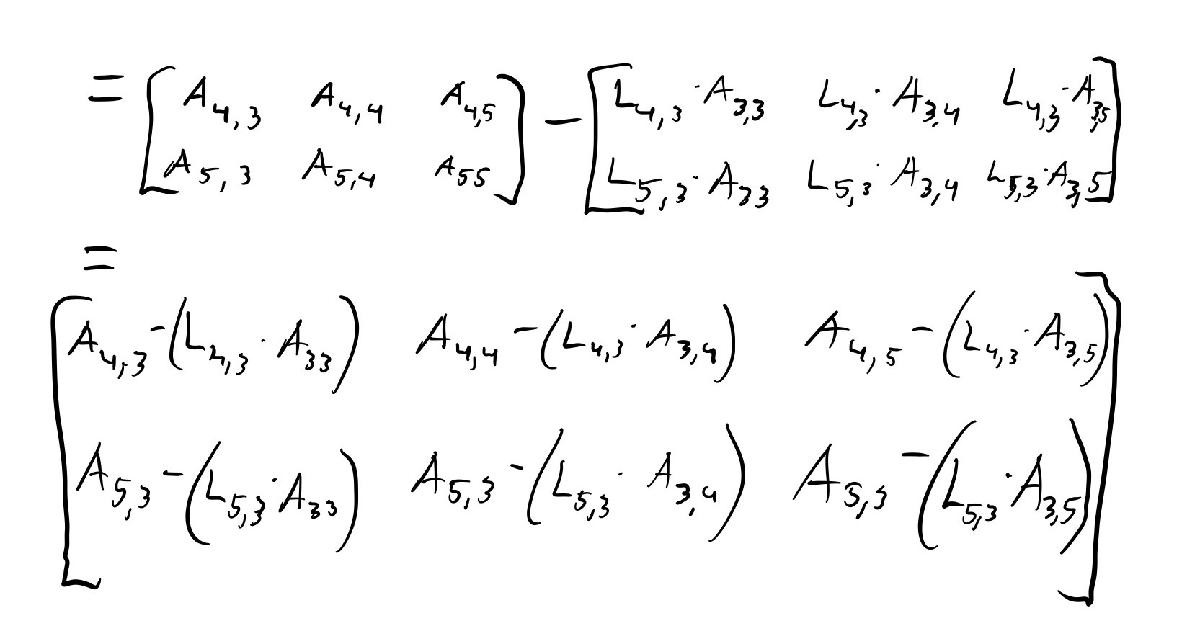

## Problem 4. 

### Part a.)

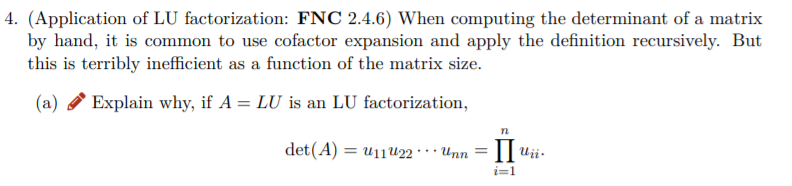

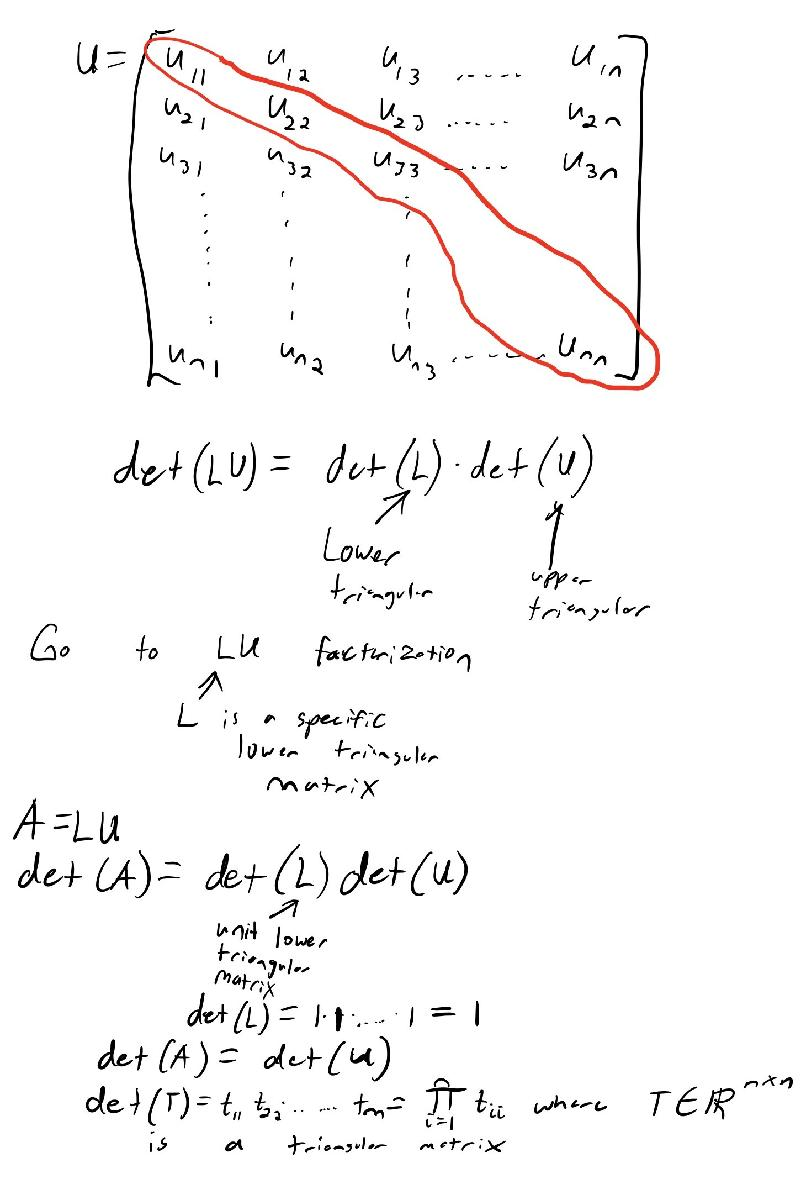

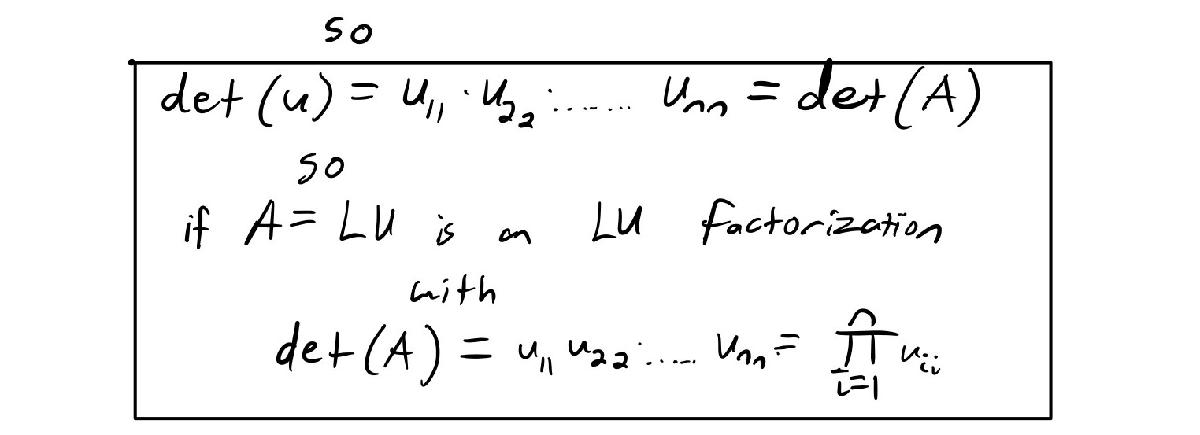

### Part b.)

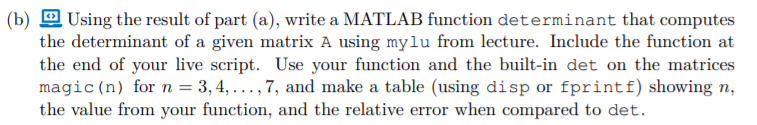

format long g
fprintf('n             det                       determinant            relative error')

n             det                       determinant            relative error

for n = 3:7
    y = magic(n);
    x = det(y);
    z = determinant(y);
    relerr = (z - x) / x;
    fprintf('%1d    %26.12f    %26.12f   %15.12f\n', n, x, z, relerr)
end

3             -360.000000000000             -360.000000000000   -0.000000000000
4                0.000000000001                0.000000000000   -0.294117647059
5          5069999.999999999069          5069999.999999997206   -0.000000000000
6                0.000000001150                0.000000000000   -1.000000000000
7    -348052801599.999938964844    -348052801600.000122070312    0.000000000000


## Problem 5. 

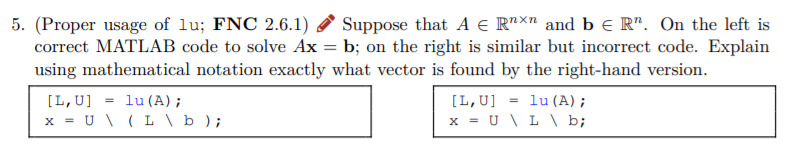

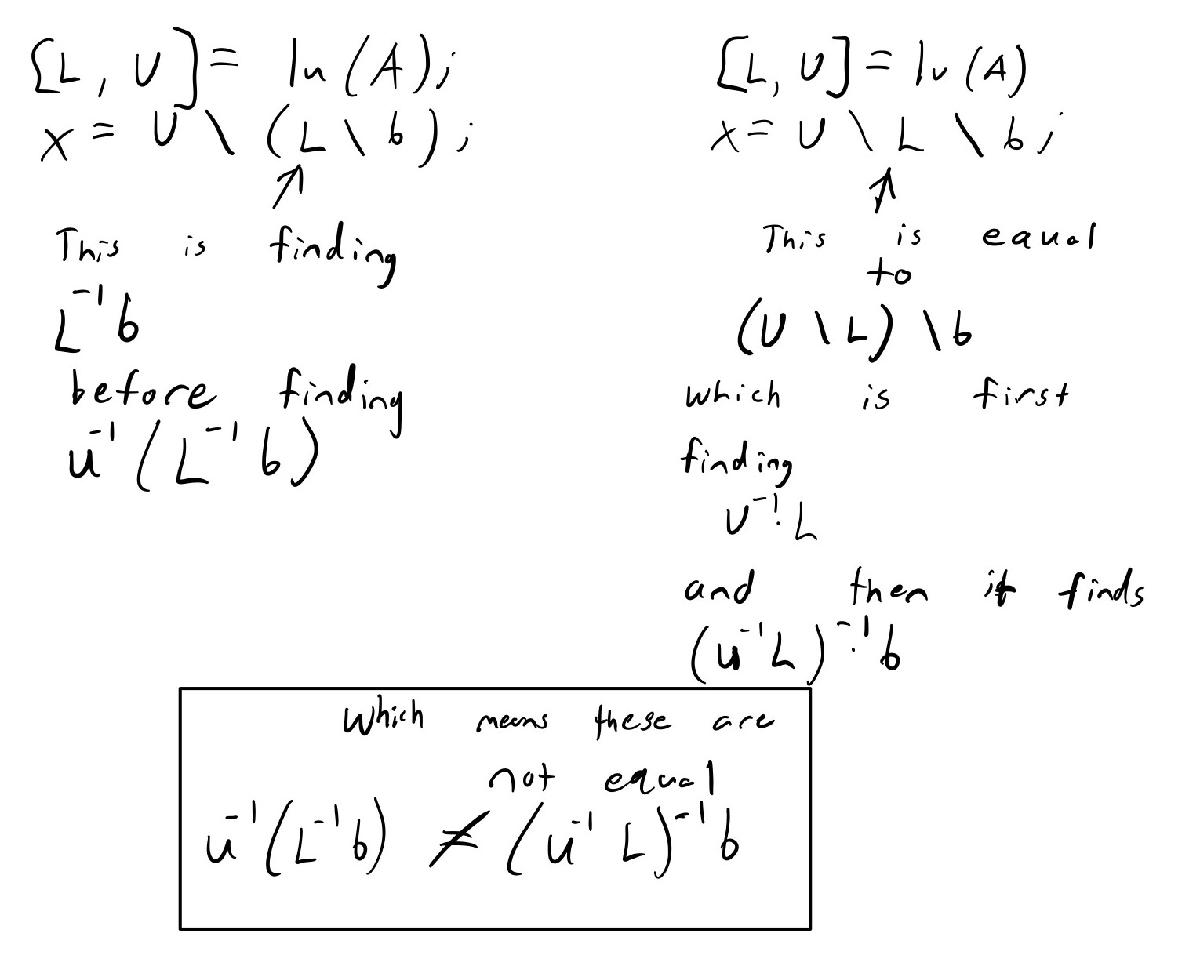

## Problem 6.

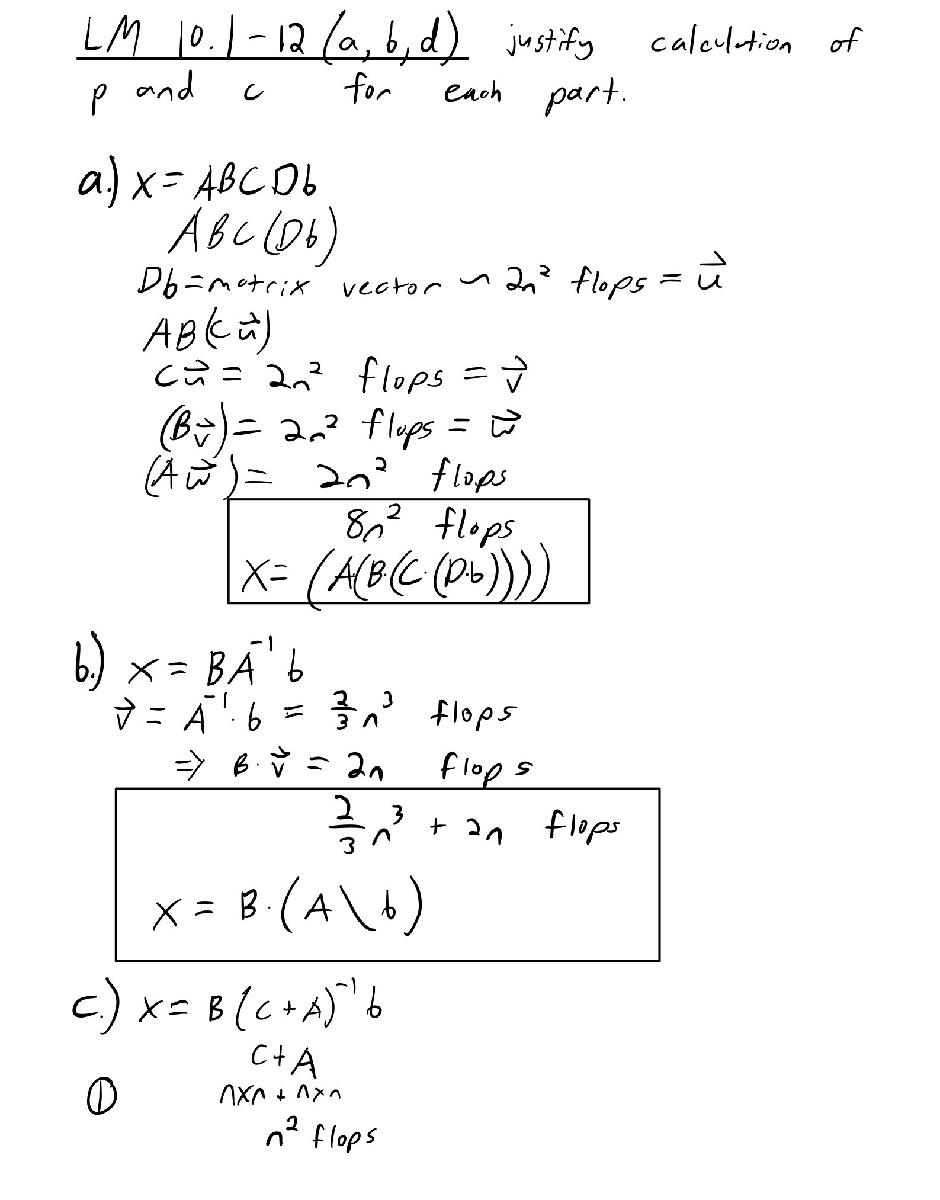

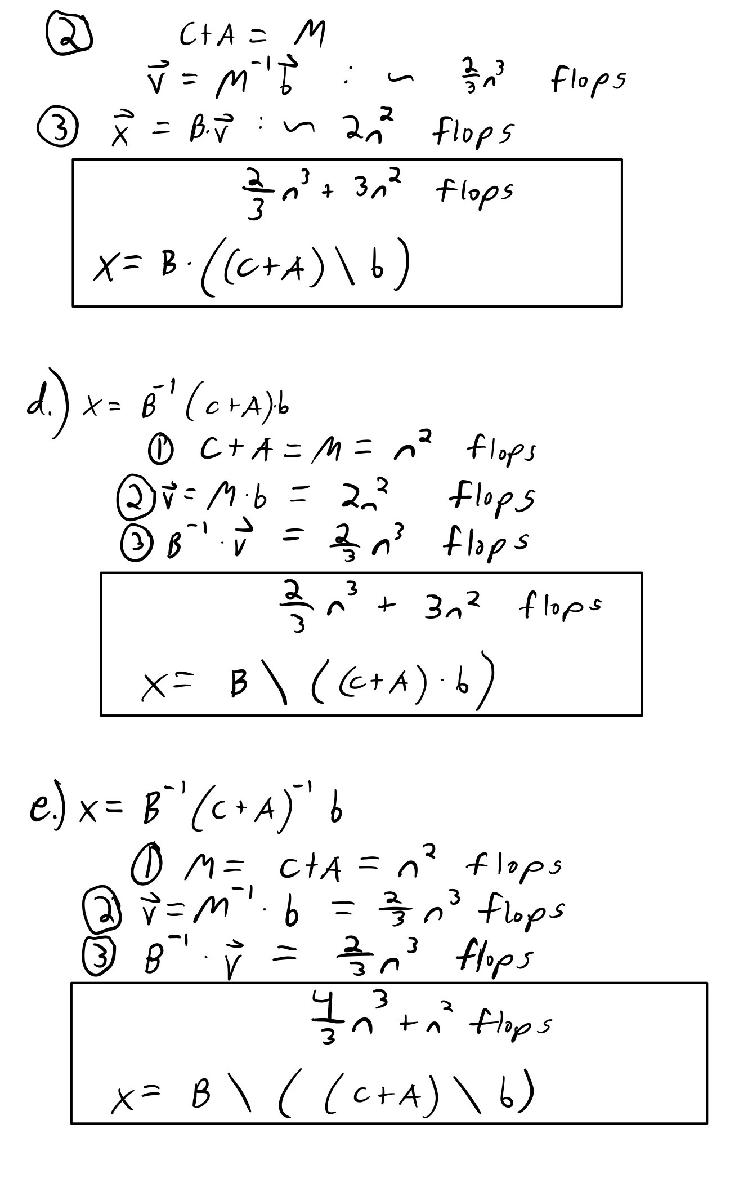

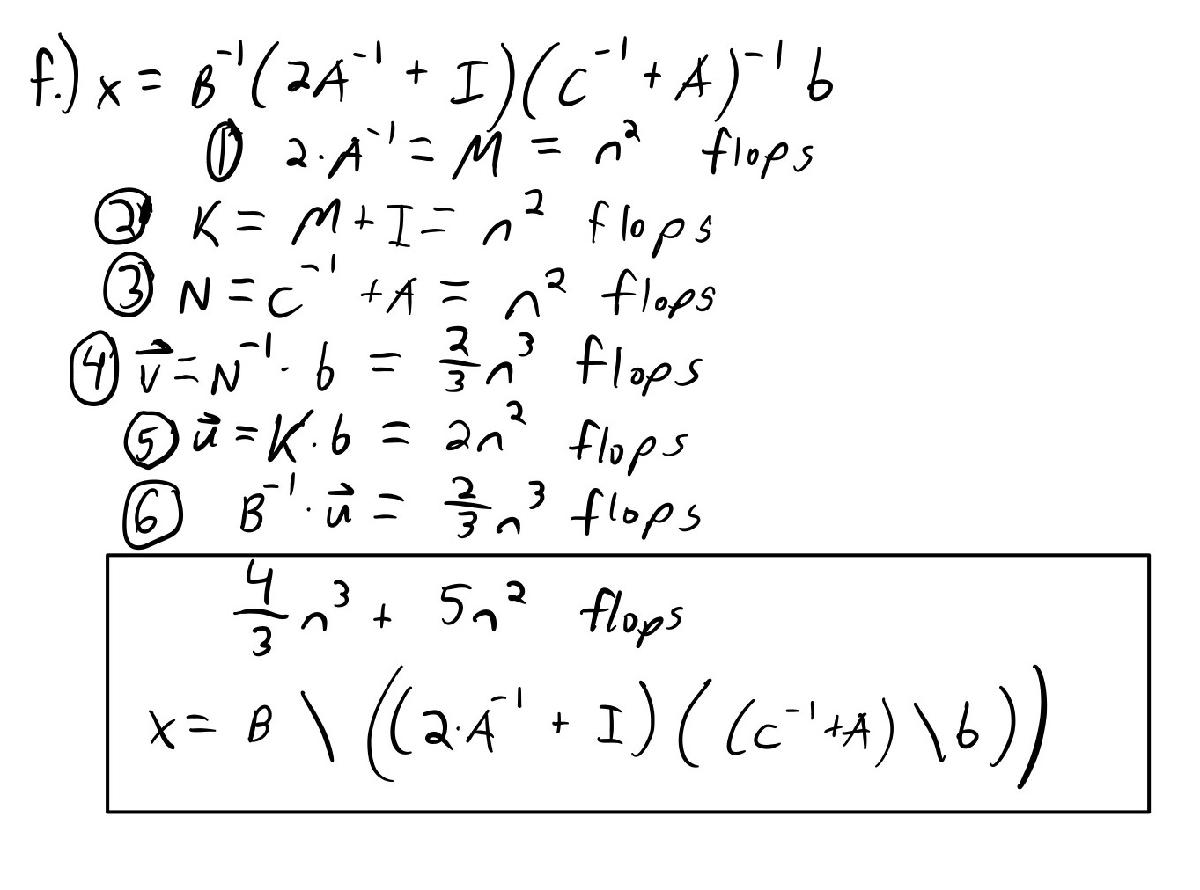

## Problem 7.

### Part a.)

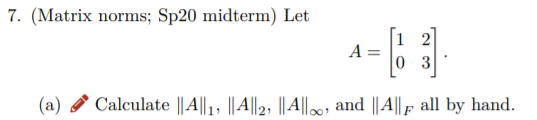

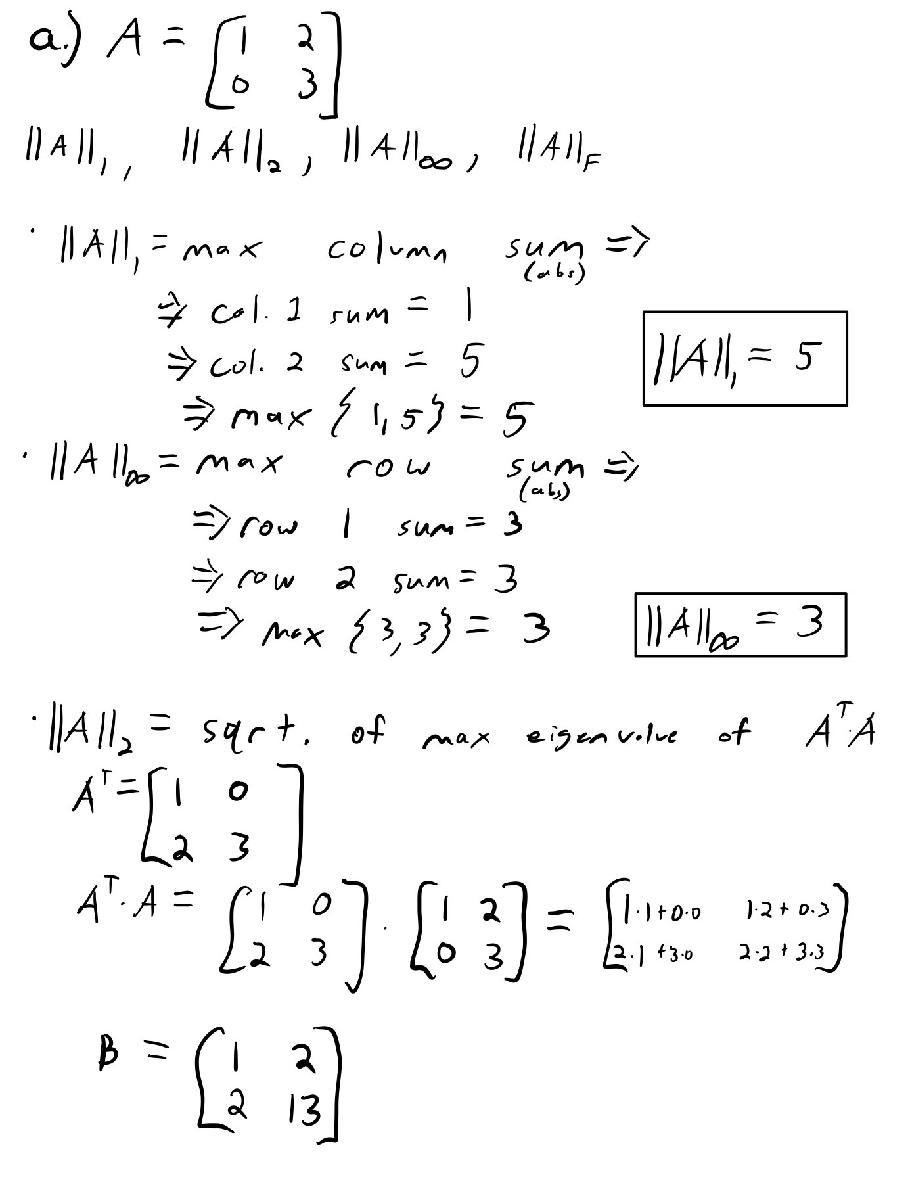

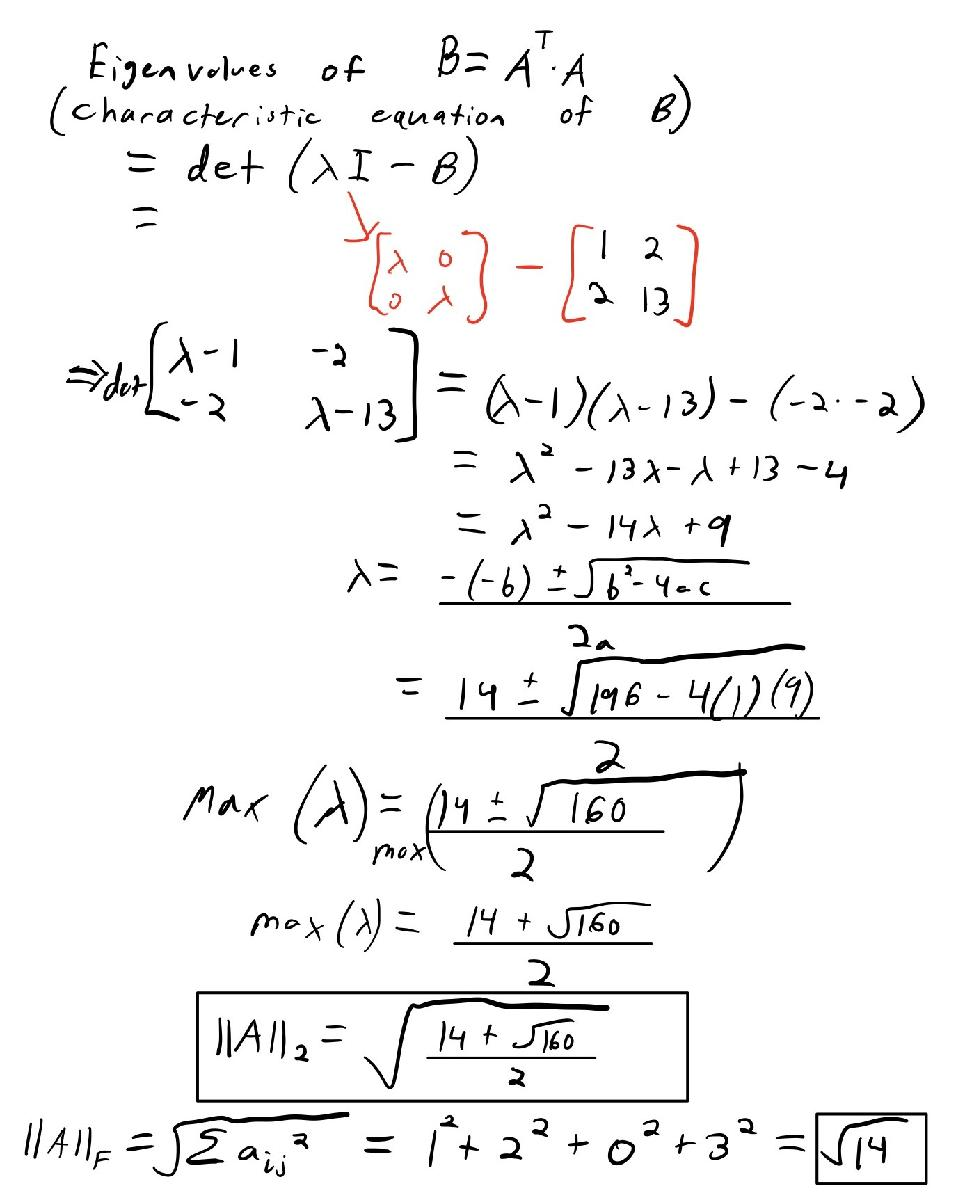

### Part b.)

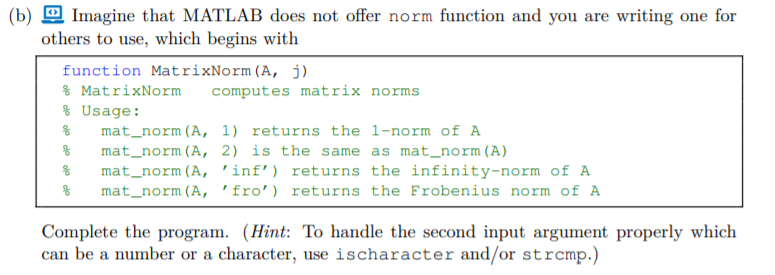

A = [1 2;
     0 3]

A =      1     2
     0     3


A1 = mat_norm(A, 1)

A1 =      5


B1 = mat_norm(A, 2)

B1 =           3.65028153987288


C1 = mat_norm(A, 'inf')

C1 =      3


D1 = mat_norm(A, 'Afro')

D1 =           3.74165738677394



A2 = norm(A, 1)

A2 =      5


B2 = norm(A, 2)

B2 =           3.65028153987288


C2 = norm(A, Inf)

C2 =      3


D2 = norm(A, 'fro')

D2 =           3.74165738677394


## Function backsub

function X = backsub(U,B)
% BACKSUB x = backsub(U,B)
% Solve an upper triangular linear system.
% Input:
% U upper triangular square matrix (n by n)
% B right-hand side vectors concatenated into an (n-by-p) matrix
% Output:
% X solution of UX = B (n-by-p)
[n,p] = size(B); % grab dimensions
X = zeros(n,p); % preallocate output
for j = 1:p
    for i = n:-1:1
        X(i,j)= ( B(i,j) - U(i,i+1:n)*X(i+1:n,j))/ U(i,i);
    end
end
end

## Function forelim

function X = forelim(L,B)
% % FORELIM x = forelim(L,B)
% % Solve a lower triangular linear system.
% % Input:
% % L lower triangular square matrix (n by n)
% % B right-hand side vector (n by p)
% % Output:
% % X solution of Lx=b (n by p matrix)
[n, p] = size(B);
X = zeros(n,p);
for j = 1:p
    for i = 1:n
        X(i,j) = (B(i,j) - L(i, 1:i-1) * X(1:i-1,j)) / L(i,i);
    end
end
end

## Function ltinverse

function X = ltInverse(L)
% % FORELIM X = ltInverse(L)
% % Solve creates the inverse of a lower triangular matrix
% % Input:
% % L lower triangular square matrix (n by n)
% % Output:
% % X solution of X = A^-1
I = eye(length(L));
X = forelim(L, I);
end

## Function myLU (from Lecture and is used to verify modified function)

function [L,U] = mylu(A)
% MYLU LU factorization (demo only--not stable!).
% Input:
% A square matrix
% Output:
% L,U unit lower triangular and upper triangular such that LU=A
n = length(A);
L = eye(n); % ones on diagonal
% Gaussian elimination
for j = 1:n-1
    for i = j+1:n
        L(i,j) = A(i,j) / A(j,j); % row multiplier
        A(i,j:n) = A(i,j:n) - L(i,j)*A(j,j:n);
    end
end
U = triu(A);
end

## Function myLUmodified

function [L,U] = myluMod(A)
% MYLU LU factorization (demo only--not stable!).
% Input:
% A square matrix
% Output:
% L,U unit lower triangular and upper triangular such that LU=A
n = length(A);
L = eye(n); % ones on diagonal
% Gaussian elimination
for j = 1:n-1
    i = j+1:n;
    L(i,j) = A(i,j) / A(j,j);  % row multiplier
    A(i,j:n) = A(i,j:n) - L(i,j)*A(j,j:n);
end
U = triu(A);
end

## Function determinant

function x = determinant(A)
% determinant computes the determinant of a matrix A = LU of an LU
% factorization by first using myLU to find the upper triangular matrix 
% input:
% A square matrix
% output:
% determinant of the matrix A
[~, U] = mylu(A); %gives us the upper triangular matrix of matrix A
x = prod(diag(U));

end

## Function Matrix Norm

function maxVal = mat_norm(A, j)
% % MatrixNorm computes matrix norms
% % Usage:
% % mat_norm(A, 1) returns the 1-norm of A
% % mat_norm(A, 2) is the same as mat_norm(A)
% % mat_norm(A, 'inf') returns the infinity-norm of A
% % mat_norm(A, 'Afro') returns the Frobenius norm of A
   
if ischar(j) == 1
    if strcmp(j,'inf') == 1
        maxVal = max(sum(abs(A), 2));
    end
    if strcmp(j,'Afro') == 1
        maxVal = sqrt(A(:)'*A(:));
    end
else 
    if j == 1
        maxVal = 0;
        for i = 1:length(A)
            x = sum(A(:,i));
            if x > maxVal
                maxVal = x;
            end
        end
    end
    if j == 2
        maxVal = max(sqrt(eig(A'*A)));
    end
end

end